clearvars -except mapCD
% loadif("D:\od\OneDrive\matlab\RawData\1T-TaS2(point defect)\mapCD.mat")
map = loadMapdt(2,1)

sG = struct with fields:
         Gfinal0T: [1741×729×1521 double]
    ImgFinalZnorm: [1741×729 double]
         Zfinal0T: [1741×729 double]
               vm: [-0.7600 -0.7590 -0.7580 -0.7570 -0.7560 -0.7550 -0.7540 -0.7530 -0.7520 -0.7510 -0.7500 -0.7490 -0.7480 -0.7470 -0.7460 -0.7450 -0.7440 -0.7430 -0.7420 -0.7410 -0.7400 -0.7390 -0.7380 -0.7370 -0.7360 -0.7350 … ] (1×1521 double)
                x: [0.0807 0.1614 0.2421 0.3228 0.4035 0.4842 0.5649 0.6456 0.7263 0.8070 0.8878 0.9685 1.0492 1.1299 1.2106 1.2913 1.3720 1.4527 1.5334 1.6141 1.6948 1.7755 1.8562 1.9369 2.0176 2.0983 2.1790 2.2597 2.3404 2.4211 … ] (1×1741 double)
                y: [0.0808 0.1615 0.2423 0.3231 0.4038 0.4846 0.5654 0.6461 0.7269 0.8076 0.8884 0.9692 1.0499 1.1307 1.2115 1.2922 1.3730 1.4538 1.5345 1.6153 1.6961 1.7768 1.8576 1.9383 2.0191 2.0999 2.1806 2.2614 2.3422 2.4229 … ] (1×729 double)


map = struct with fields:
           Gap0Tn: [1361×621 double]
           Gap0Tp: [1361×621 double]
         Gfinal0T: [1361×621×1521 double]
    ImgFinalZnorm: [1361×621 double]
         Zfinal0T: [1361×621 double]
               vm: [-0.7600 -0.7590 -0.7580 -0.7570 -0.7560 -0.7550 -0.7540 -0.7530 -0.7520 -0.7510 -0.7500 -0.7490 -0.7480 -0.7470 -0.7460 -0.7450 -0.7440 -0.7430 -0.7420 -0.7410 -0.7400 -0.7390 -0.7380 -0.7370 -0.7360 -0.7350 … ] (1×1521 double)
                x: [11.2986 11.3793 11.4601 11.5408 11.6215 11.7022 11.7829 11.8636 11.9443 12.0250 12.1057 12.1864 12.2671 12.3478 12.4285 12.5092 12.5899 12.6706 12.7513 12.8320 12.9127 12.9934 13.0741 13.1548 13.2356 13.3163 … ] (1×1361 double)
                y: [4.8459 4.9266 5.0074 5.0882 5.1689 5.2497 5.3304 5.4112 5.4920 5.5727 5.6535 5.7343 5.8150 5.8958 5.9766 6.0573 6.1381 6.2189 6.2996 6.3804 6.4611 6.5419 6.6227 6.7034 6.7842 6.8650 6.9457 7.0265 7.1073 7.1880 … ] (1×621 double)


map.

## Quick Review of Coulomb Bloackade

### in case of I-V curve

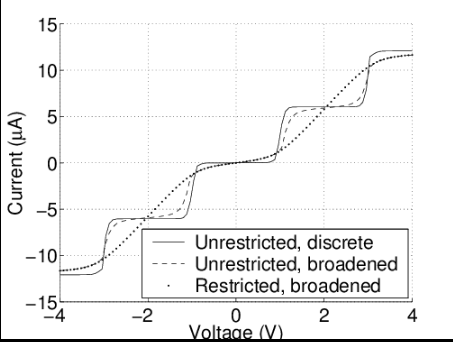

similar to step function.

### in case of G-V curve

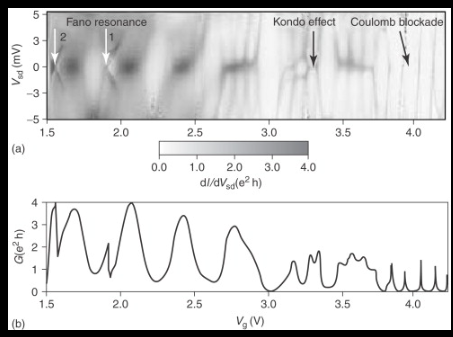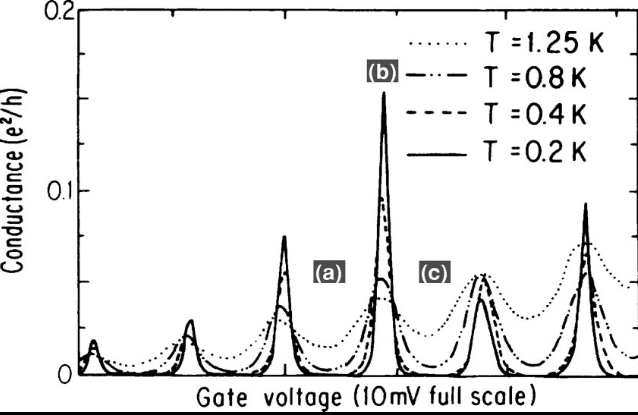

Ideally it is similar to Dirac comb.

## Our Dataset

### Survey global feature(Review previous data processing)

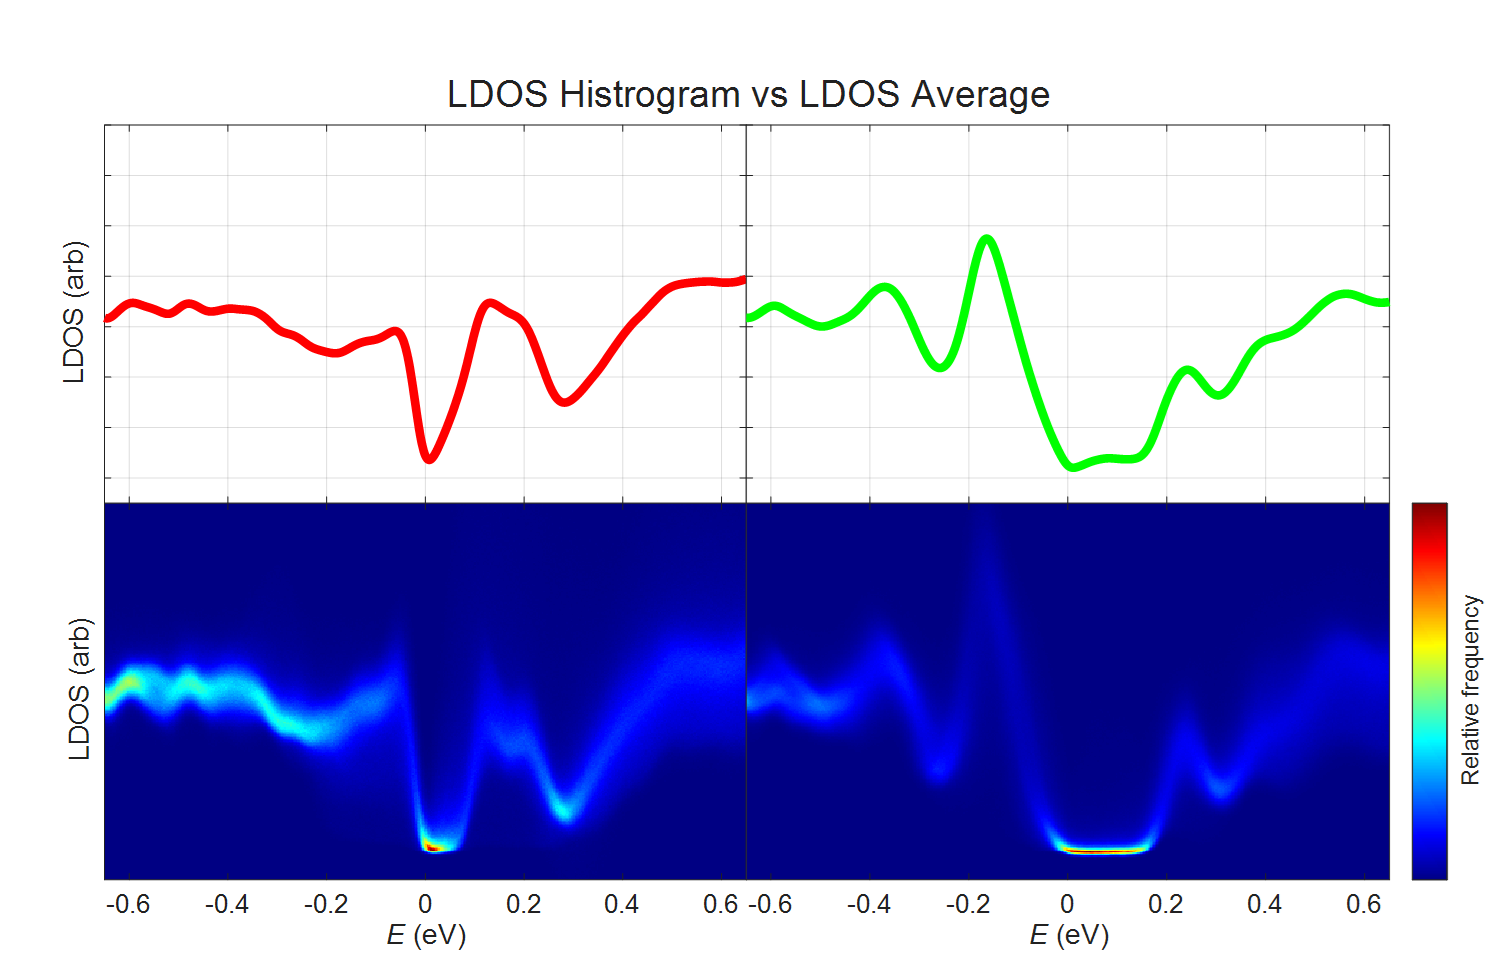

At glace, it is more visible in negative side.

In c-type(Mott case), step feature(~100mV) exist.

In a-type(trivial case), step featre(~200mV) exist but unclear.

### Survey local feature

To survey "quantum blockade" truly exist, we perform FFT.

I think it works well as I intended

#### Parameter

% iph = 1
xypxl = [330 50]

xypxl =    330    50


vCrop = [-0.8 -0.2]

vCrop =    -0.8000   -0.2000


#### Figure setting

f = figure(1)

f =   Figure (refinepeaks) with properties:

      Number: 1
        Name: ''
       Color: [0.9608 0.9608 0.9608]
    Position: [423 -423 1920 990]
       Units: 'pixels'

  Show all properties


f.Visible = 'on'

f =   Figure (refinepeaks) with properties:

      Number: 1
        Name: ''
       Color: [0.9608 0.9608 0.9608]
    Position: [423 -423 1920 990]
       Units: 'pixels'

  Show all properties


#### Topo

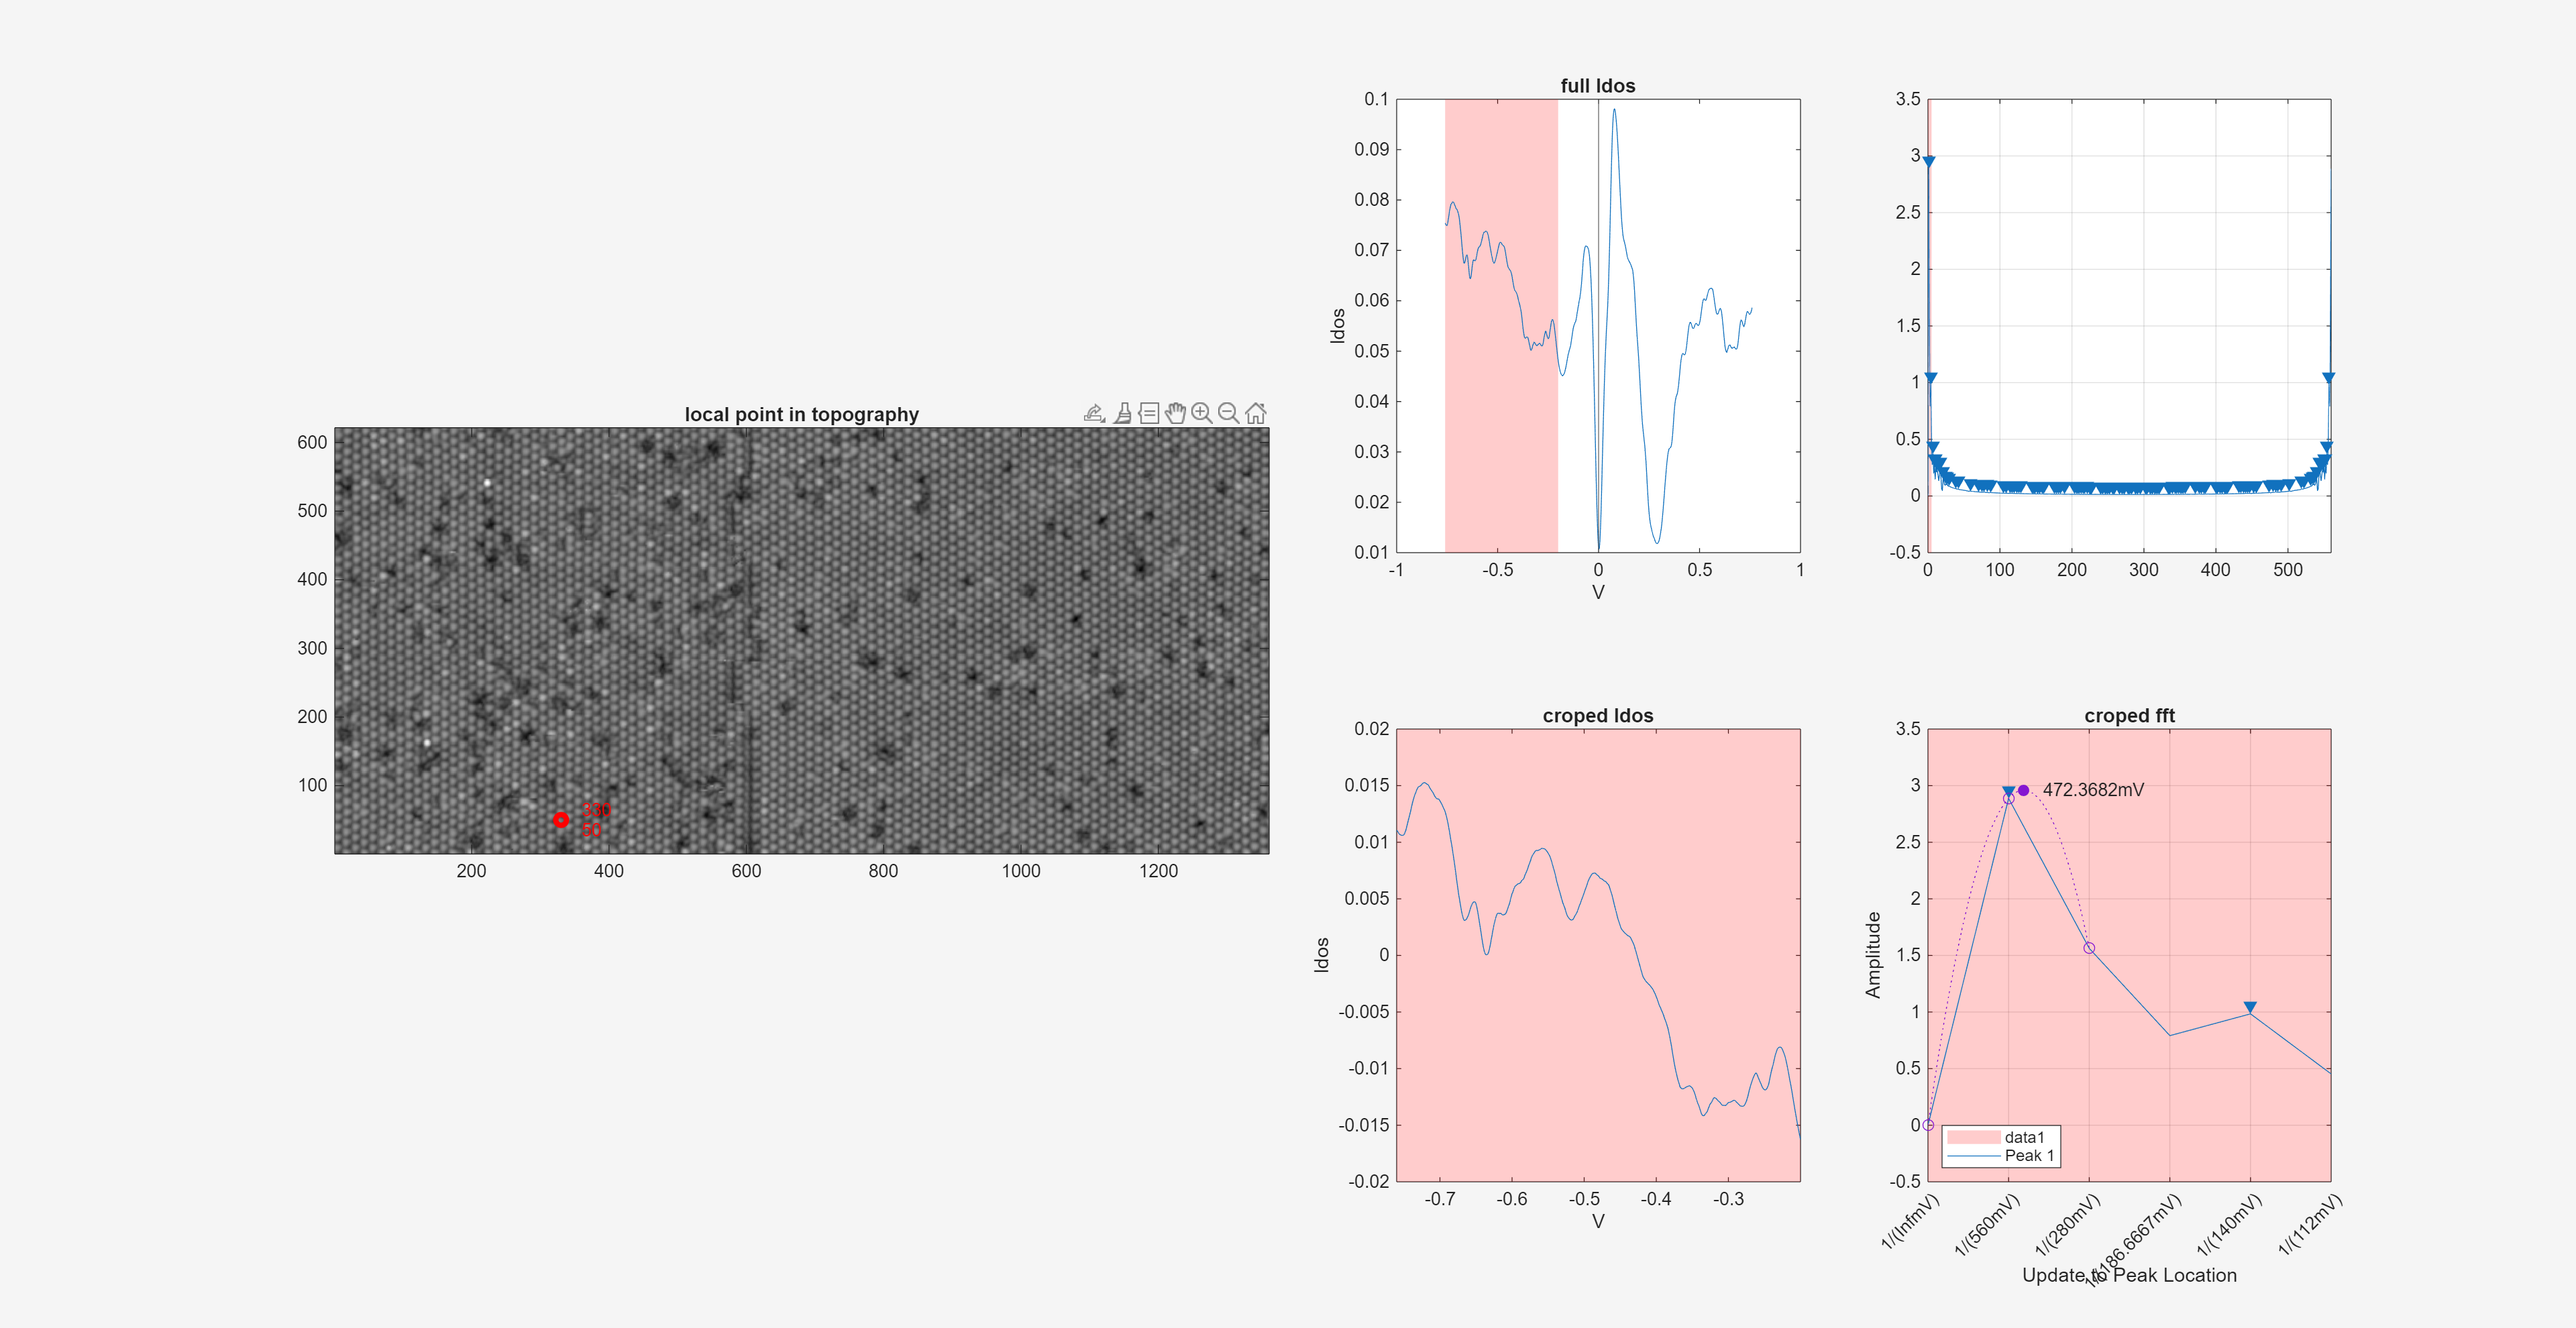

subplot(2,4,[1 2 5 6])

Z = map.Zfinal0T %mapCD.dt(iph).Z;

Z =     0.0894    0.0902    0.0914    0.0988    0.1061    0.1142    0.1210    0.1233    0.1253    0.1240    0.1231    0.1189    0.1153    0.1075    0.0994    0.0917    0.0852    0.0880    0.0920    0.0997    0.1079    0.1155    0.1232    0.1255    0.1269    0.1249    0.1226    0.1169    0.1108    0.1032    0.0957    0.0933    0.0933    0.0983    0.1049    0.1113    0.1177    0.1222    0.1259    0.1254    0.1231    0.1190    0.1140    0.1070    0.0981    0.0919    0.0879    0.0898    0.0960    0.1012
    0.0863    0.0944    0.0959    0.1043    0.1126    0.1202    0.1281    0.1323    0.1366    0.1358    0.1336    0.1274    0.1217    0.1115    0.1018    0.0943    0.0876    0.0924    0.0974    0.1061    0.1150    0.1225    0.1298    0.1336    0.1371    0.1364    0.1331    0.1254    0.1172    0.1076    0.0981    0.0955    0.0957    0.1027    0.1121    0.1198    0.1270    0.1313    0.1343    0.1347    0.1336    0.1304    0.1243    0.1150    0.1038    0.0962    0.0915    0.0926    0.0998    0


views(Z)


colormap gray
hold on
plot(xypxl(1),xypxl(2),'ro',LineWidth=3)
text(xypxl(1)+30,xypxl(2),string(xypxl),Color='r')
hold off
title('local point in topography')
fftCrop = [0 5];

#### full ldos

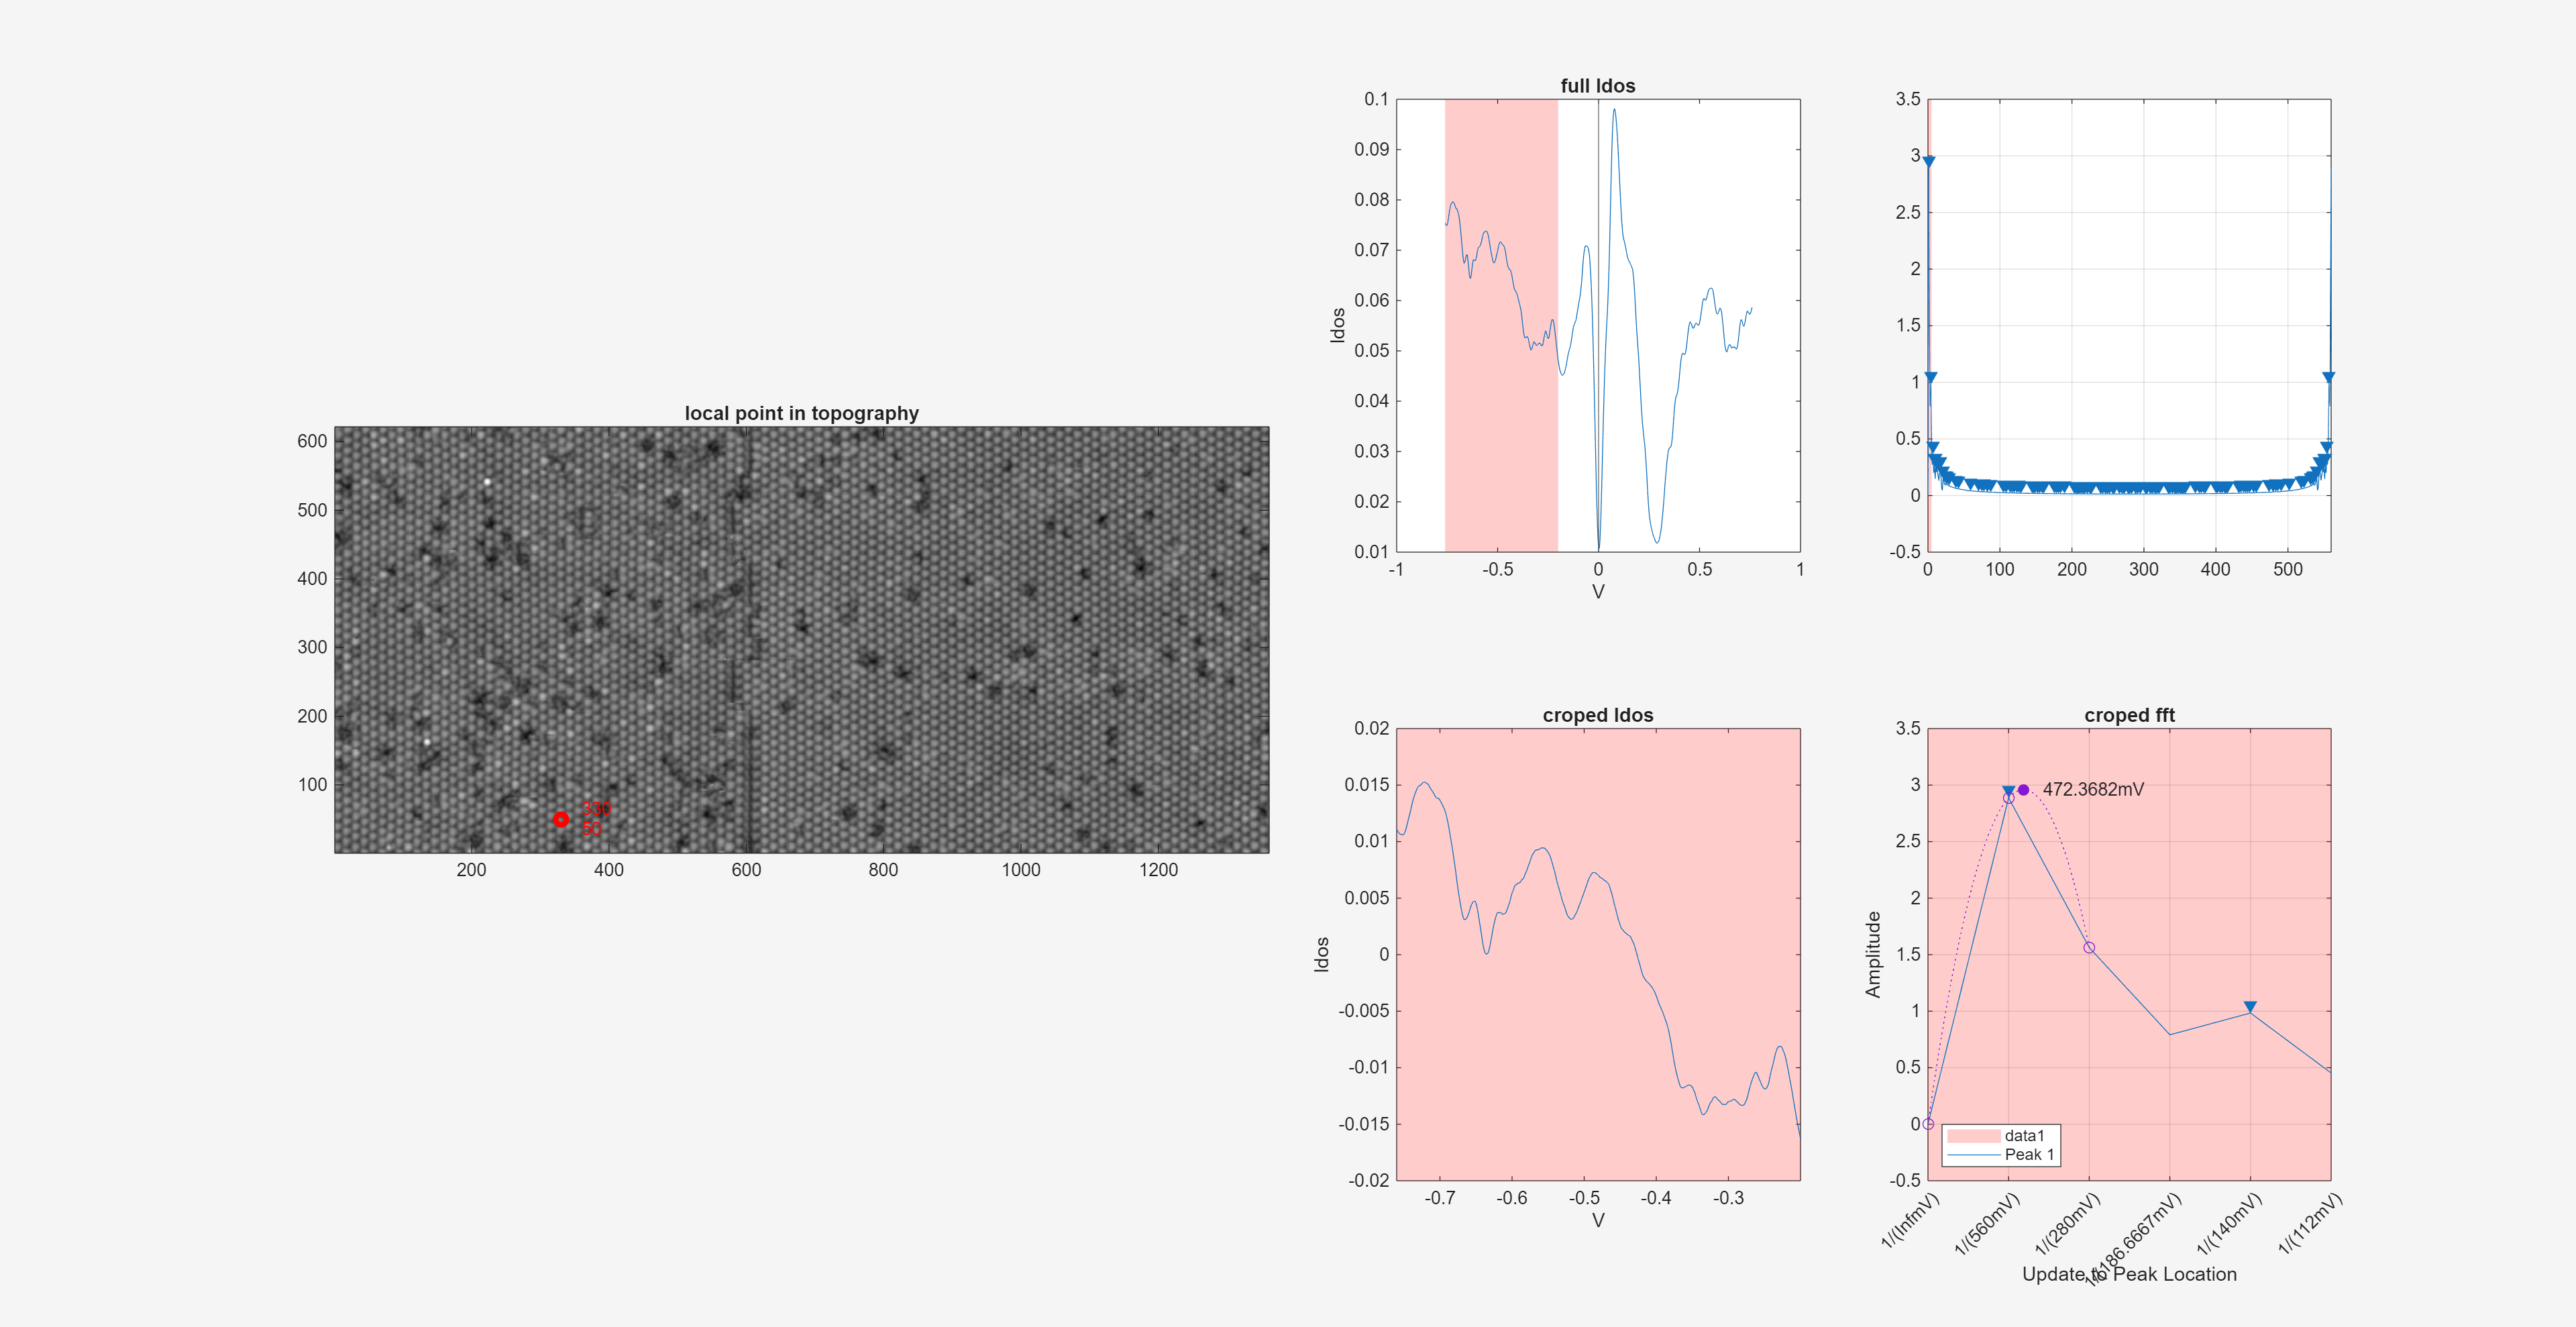

subplot(2,4,3)

v = map.vm %mapCD.V;

v =    -0.7600   -0.7590   -0.7580   -0.7570   -0.7560   -0.7550   -0.7540   -0.7530   -0.7520   -0.7510   -0.7500   -0.7490   -0.7480   -0.7470   -0.7460   -0.7450   -0.7440   -0.7430   -0.7420   -0.7410   -0.7400   -0.7390   -0.7380   -0.7370   -0.7360   -0.7350   -0.7340   -0.7330   -0.7320   -0.7310   -0.7300   -0.7290   -0.7280   -0.7270   -0.7260   -0.7250   -0.7240   -0.7230   -0.7220   -0.7210   -0.7200   -0.7190   -0.7180   -0.7170   -0.7160   -0.7150   -0.7140   -0.7130   -0.7120   -0.7110


G = map.
ldos = squeeze(mapCD.dt(iph).G(xypxl(1),xypxl(2),:));

Unable to resolve the name 'mapCD.dt'.

plot(v,ldos);
xline(0)
xlabel('V')
ylabel('ldos')
title('full ldos')

[~,ind] = min(abs(v'-vCrop))
% xline(v(ind),'--','crop')
vind = v(ind);
highlightXRange(vind)


#### croped ldos

subplot(2,4,7)
iCr = ind(1):ind(2);
vCr = v(iCr);
ldosCr = ldos(iCr);
ldosCr = ldosCr - mean(ldosCr)
% ldosCr = sin(iCr)
plot(vCr,ldosCr)
xlabel('V')
ylabel('ldos')
title('croped ldos')
highlightXRange(vind)
xlim(vind)

#### full fft

subplot(2,4,4)
fs = (1:length(ldosCr))-1
abfft = abs(fft(ldosCr));
xlabel("f(1/T unit)")
title("full fft")

findpeaks(abfft,fs)
highlightXRange(fftCrop)

#### croped fft

subplot(2,4,8)

plot(fs,abfft,'r')

ax = gca
xlim(fftCrop)

findpeaks(abfft,fs)
[pks,idx] = findpeaks(abfft,fs)
hold on
idx_pkcand =  idx(1)
refinepeaks(abfft,idx_pkcand + 1)
% ax.Children.DisplayName
% findobj(ax, 'DisplayName', '(RefinedCurve)')
ax.Children
hold off
xlim(fftCrop)
highlightXRange(fftCrop)
title("croped fft")
rfobj = findobj(ax,{'Tag'},{'RefinedCurve';'InitialPeak';'EdgeSample';'RefinedPeak'})
for idx = 1:length(rfobj)
rfobj(idx).XData = rfobj(idx).XData + idx_pkcand
end
rfobj(1).LineStyle = ':'
T = abs(vind(1)-vind(2))*1000

str = "    "+string(T/rfobj(4).XData) +"mV"
hold on
text(rfobj(4).XData,rfobj(4).YData,str)
hold off
(T)./(ax.XTick)
string(T./ax.XTick)
ax.XTickLabel =  ("1/("+string(T./ax.XTick) +"mV)")'
ax.XTickLabelRotation = 45

function h = highlightXRange(x_minmax, color, alpha)
% HIGHLIGHTXRANGE Highlights a specific x-range on the current axes
%
% Inputs:
%   x_minmax - Two-element vector [x_min, x_max] specifying the region to highlight
%   color    - Color of the highlight (default: 'red')
%   alpha    - Opacity level from 0 to 1 (default: 0.2)
%
% Output:
%   h        - Handle to the created patch object
%
% Example:
%   plot(1:10, sin(1:10));
%   highlightXRange([3, 6], 'blue', 0.3);

% Validate input
if ~isvector(x_minmax) || length(x_minmax) ~= 2
    error('x_minmax must be a two-element vector [x_min, x_max]');
end

x_min = min(x_minmax);
x_max = max(x_minmax);

% Handle default parameters
if nargin < 2 || isempty(color)
    color = 'red';
end

if nargin < 3 || isempty(alpha)
    alpha = 0.2;
end

% Get current axis limits
ax = gca;
y_limits = ylim(ax);

% Create patch coordinates
x_patch = [x_min, x_max, x_max, x_min];
y_patch = [y_limits(1), y_limits(1), y_limits(2), y_limits(2)];

% Create the patch
h = patch(x_patch, y_patch, color, 'FaceAlpha', alpha, 'EdgeColor', 'none');

% Make sure the patch stays in the background
uistack(h, 'bottom');

% Ensure the y-limits don't change due to the patch
ylim(y_limits);

end